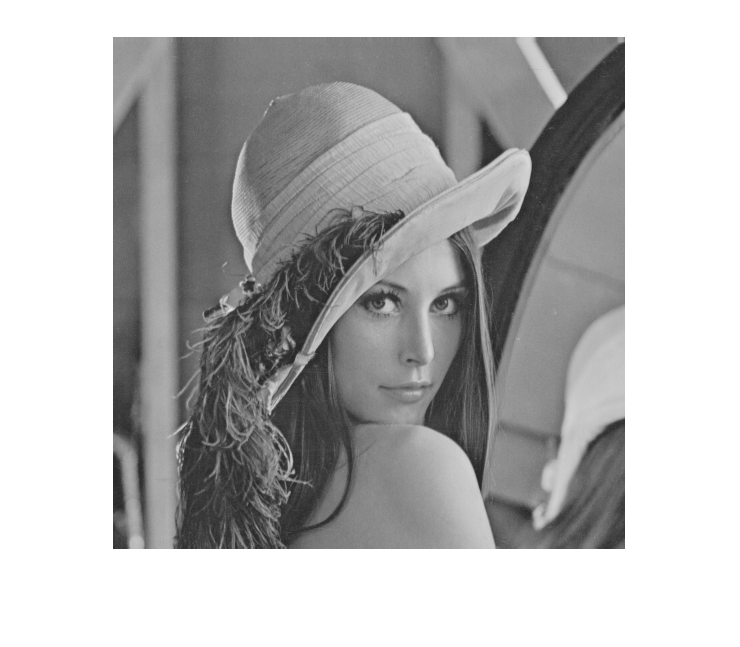

img=imread("lena.tiff");
img=rgb2ycbcr(img);
imgy=img(:,:,1);
imshow(imgy);

[m,n]=size(imgy);
Y_table=[16 11 10 16 24 40 51 61;
         12 12 14 19 26 58 60 55;
         14 13 16 24 40 57 69 56;
         14 17 22 29 51 87 80 62;
         18 22 37 56 68 109 103 77;
         24 35 55 64 81 104 113 92 ;
         49 64 78 87 103 121 120 101;
         72 92 95 98 112 100 103 99];
zigzag=[1,2,9,17,10,3,4,11,...
        18,25,33,26,19,12,5,6,...
        13,20,27,34,41,49,42,35,...
        28,21,14,7,8,15,22,29,...
        36,43,50,57,58,51,44,37,...
        30,23,16,24,31,38,45,52,...
        59,60,53,46,39,32,40,47,...
        54,61,62,55,48,56,63,64];
    
inzigzag=[1,2,6,7,15,16,28,29;
          3,5,8,14,17,27,30,43;
          4,9,13,18,26,31,42,44;
          10,12,19,25,32,41,45,54;
          11,20,24,33,40,46,53,55;
          21,23,34,39,47,42,56,61;
          22,35,38,48,51,57,60,62;
          36,37,49,50,58,59,63,64];
i=1;
j=1;
new_image=zeros(m,n);
mid=zeros(m,n);
mid_img=zeros(4096,64);
t=0;
while(i<m)
    j=1;
    while(j<n)
        t=t+1;
        block=imgy(i:i+7,j:j+7);
        block=dct2(block);
        new_block=round(block./Y_table);
        for q=1:64
            indx=mod(zigzag(1,q),8);
            if indx==0
                indx=8;
            end
            indx2=floor(zigzag(1,q)/8)+1;
            if indx2==9
                indx2=8;
            end
            mid_img(t,q)=new_block(indx2,indx);
        end
        new_block=new_block.*Y_table;
        
        new_block=round(idct2(new_block));
        new_image(i:i+7,j:j+7)=new_block;
        j=j+8;
    end
    i=i+8;
end

static=tabulate(mid_img(:));
sort_static=sortrows(static,2,"descend");
num12=sum(sort_static(13:139,3));


Tr=zeros(13,2);
Tr(1:12,1)=sort_static(1:12,1);
Tr(1:12,2)=sort_static(1:12,3);
Tr(13,1)=999;
Tr(13,2)=num12;
Tr=sortrows(Tr,2,"descend");
[result,head]=huff(Tr);
result{end+1}=head;
[a,~]=size(result);
flip(result);
table={};
con=1;
stack=[];
for t=1:a
    temp=result{t,1};
    if (isempty(temp.child_b)==1&&isempty(temp.child_s)==1)
        remain_value=temp.mark;
        stack=[];
        while(temp.value~=100)
            stack=[temp.binary stack];
            for q =1:a
                if (temp.parent.value==result{q,1}.value)
                    temp=result{q,1};
                    break
                end
            end

        end
        table{con,1}=remain_value;
        table{con,2}=stack;
        con=con+1;
    end
    
end
prefix=[];
[a,~]=size(table);
table2={};
for t=1:a
    [~,b]=size(table{t,2});
    gama=[];
    for j=1:b
        str1=int2str(table{t,2}(1,j));
        gama=[gama str1];
    end
    table2{t,1}=table{t,1};
    table2{t,2}=gama;
    if (table{t,1}==999)
        prefix=table2{t,2};
    end
end
left=sort_static(13:end,:);
[a,~]=size(left);
for  t=1:a
    table2{con,1}=left(t,1);
    remain=dec2bin(t,7);
    table2{con,2}=[prefix remain];
    con=con+1;
end
[m,n]=size(mid_img);
mid_img2=strings(m,n);
keyset=table2(:,1);
valueset=table2(:,2);
M = containers.Map(keyset,valueset);
keyset=table2(:,2);
valueset=table2(:,1);
reverseM=containers.Map(keyset,valueset);
for i=1:m
    for j=1:n
        mid_img2(i,j)=M(mid_img(i,j));
    end
end
%encode-result
mid_img2;

%decode
mid_img3=zeros(m,n);
for i=1:m
    for j=1:n
        mid_img3(i,j)=reverseM(mid_img2(i,j));
    end
end
[m,n]=size(imgy);
[r,c]=size(mid_img3);
mid_img4=zeros(m,n);
for i=1:r
    block=zeros(8,8);
    for q=1:8
        for p=1:8
            block(q,p)=mid_img3(i,inzigzag(q,p));
        end
    end
    block=block.*Y_table;
    block=round(idct2(block));
    indx=mod(i,64);
    indx2=floor(i/64)+1;
    if (indx==0)
        indx=64;
        indx2=indx2-1;
    end
    mid_img4((indx2-1)*8+1:(indx2)*8,(indx-1)*8+1:(indx)*8)=block;
end
mid_img4=uint8(mid_img4);
test_block=imgy(1:8,505:512);
result_block=mid_img4(1:8,505:512);
encode=mid_img2(64,:);
rootmean=root_mean(test_block,result_block)

rootmean = 4.3786

snr=SNR(test_block,result_block)

snr = 969.5591

ratio=compress_ratio(encode)

ratio = 3.6056

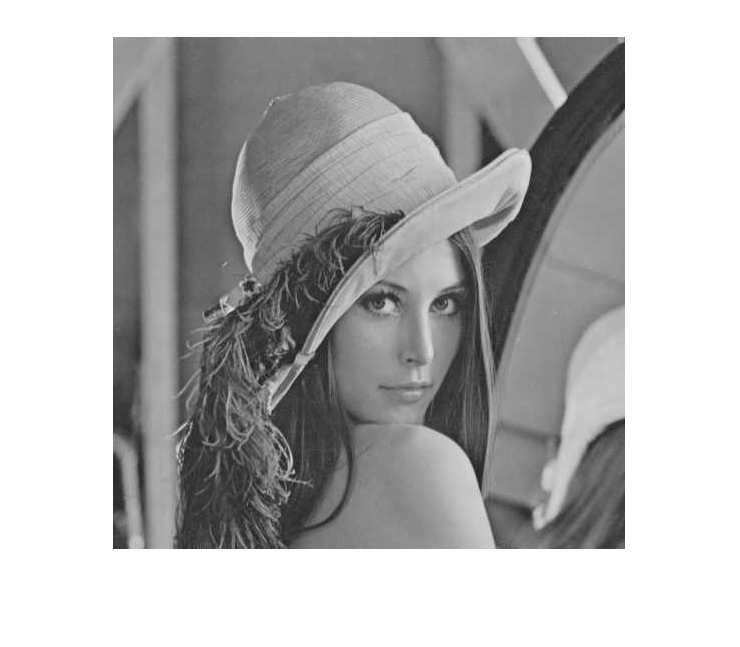

result_code=reshape(encode,8,8);
imshow(uint8(mid_img4));